# **PCA-Based Dimensionality Reduction and K-means Clustering**: EEG data Analysis_#4 

## **1. PCA  Basics**

clc; clear; close all;

**Load Data**

: use built-in** 'fisheriris'** dataset, which contains data on sepal length, sepal width, petal length, and petal width of the plant

load("fisheriris.mat")

**Select Features**

% remove one species (setosa) to make it 2-class problem
idx_mask = ~strcmp(species, 'setosa');

% select 2 features
X = meas(idx_mask, 3:4); % petal length, petal width
y = species(idx_mask);   % setosa, versicolor

**Apply PCA**

: use built-in PCA function '*pca*'

% PC: A matrix where each column represents a principal component(PC)
% score: The transformed data in the new principal component space
% latent: A vector containing the eigenvalues of the covariance matrix of X
% explained: A vector that shows the percentage of the total variance explained by each principal component

[PC, score, latent, ~, explained] = pca(X);


disp(PC)

    0.9098   -0.4151
    0.4151    0.9098



disp(explained)

   94.3500
    5.6500



**Plot PC axis**

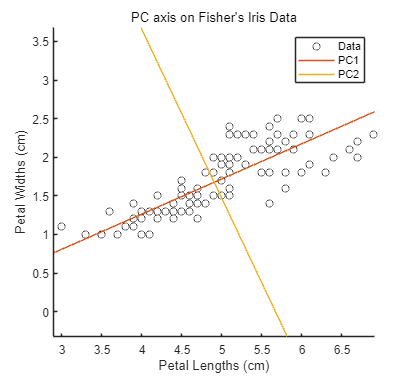

axis = PC;

figure('Position',[200,200,460,420]); hold on
plot(X(:,1),X(:,2),'ko')
x_range = mean(X(:,1))-2:0.01:mean(X(:,1))+2;
slope1 = axis(2,1)/axis(1,1);
slope2 = axis(2,2)/axis(1,2);
pc1 = (x_range-mean(X(:,1))).*slope1 + mean(X(:,2));
pc2 = (x_range-mean(X(:,1))).*slope2 + mean(X(:,2));
plot(x_range,pc1);
plot(x_range,pc2);
xlim([mean(X(:,1))-2 mean(X(:,1))+2])
ylim([mean(X(:,2))-2 mean(X(:,2))+2])
legend('Data','PC1','PC2')
title('PC axis on Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel( 'Petal Widths (cm)');

## **2. PCA  for Time Series Data**

clc; clear; close all;

**Load Data**

: 1000 observation with channel x time-step matrix

load('WaveformData.mat')
size(data)

ans =         1000           1


numCh = size(data{1}, 1)

numCh = 3

**Extract one of the Waveforms**

idx = 5;
Y = data{idx};

**Check the Waveform**

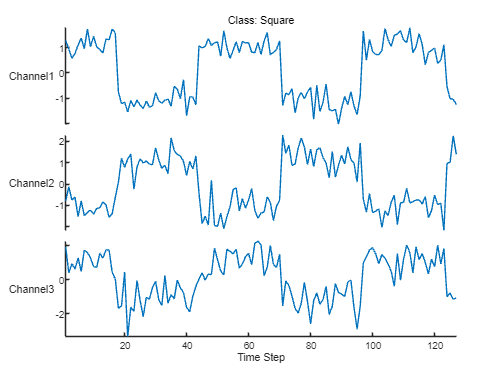

stackedplot( Y', 'DisplayLabels', ["Channel"+string(1:numCh)] );
xlabel("Time Step")
title("Class: " + string( labels(idx) ))

**Apply PCA**

% PC: A matrix where each column represents a principal component(PC)
% score: The transformed data in the new principal component space
% latent: A vector containing the eigenvalues of the covariance matrix of X
% explained: A vector that shows the percentage of the total variance explained by each principal component

[PC,~,~,~,explained]= pca(Y');


disp(PC)

    0.5451   -0.1820    0.8184
   -0.5740    0.6305    0.5225
    0.6111    0.7546   -0.2392



disp(explained)

   87.0085
    8.6651
    4.3264



% Choose PC axis
k = 1:2;

% Projecting the time-series data onto the principal components
Y_proj = PC(:, k)' * Y;
% Reconstruct
Y_recon = PC(:,k)*Y_proj;

**Check the Result**

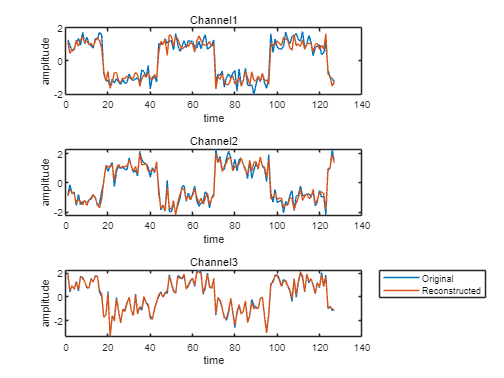

% plot the original and reconstructed data
figure;
tiledlayout(3,1);
for i = 1:3
    nexttile
    plot(Y(i,:))
    title(['Channel' num2str(i)])
    hold on
    plot(Y_recon(i,:))
    xlabel('time')
    ylabel('amplitude')
end
legend('Original','Reconstructed','Location','northeastoutside')

## **3. K-means Clustering Using PCA**

clc; clear; close all;

**Load Data**

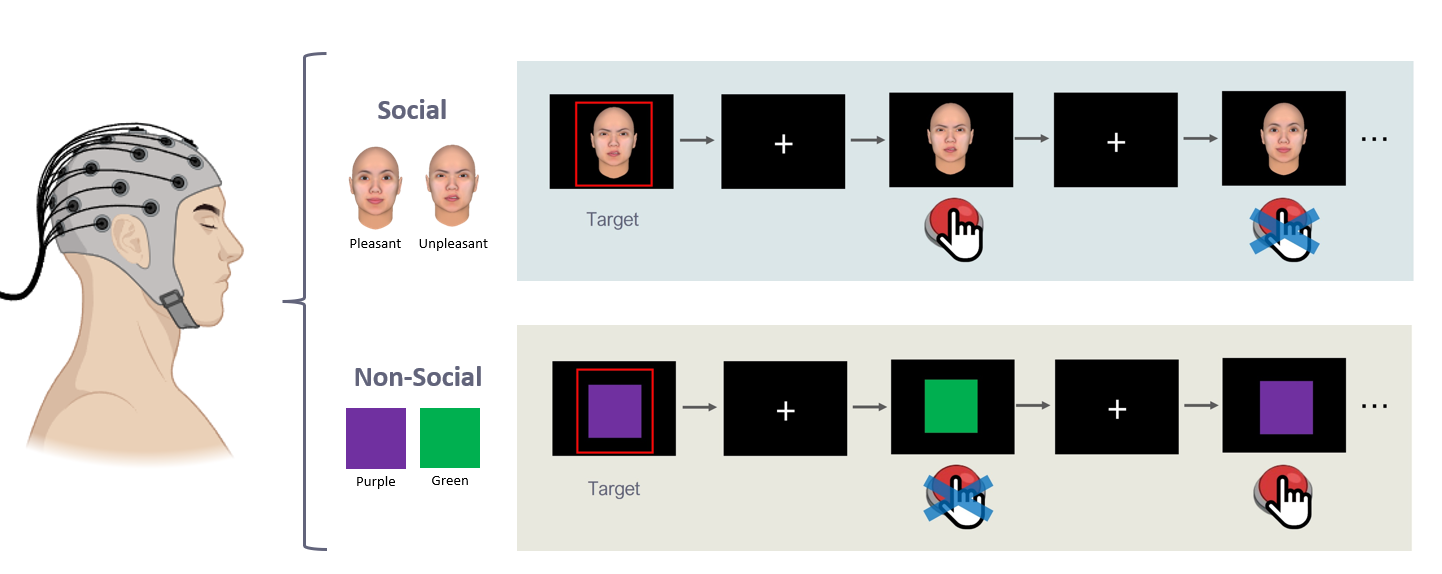

data = importdata('data_eeg.mat');
data

data = 다음 필드를 포함한 1×10 struct 배열:
    eeg
    IsPatients
    eventlabel
    eventstamp
    fs


**Data Info**

**(1) channel info**

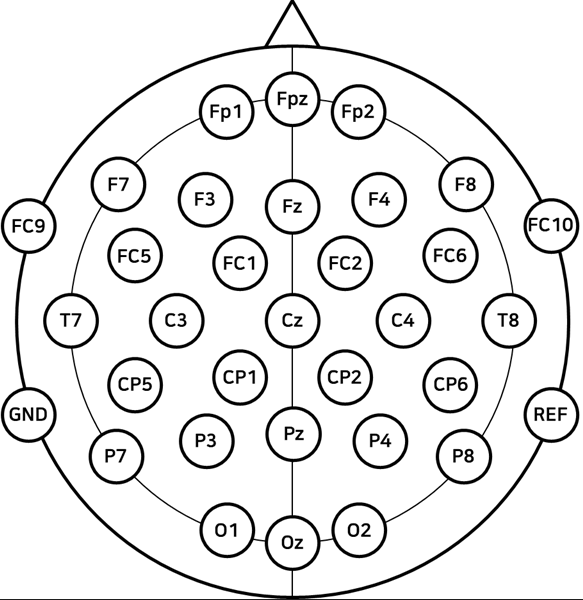

ChanName = {'Fp1', 'Fpz', 'Fp2','F7','F3','Fz','F4','F8','FC9','FC5','FC1', ...
    'FC2','FC6','FC10','T7','C3','Cz','C4','T8','CP5','CP1','CP2','CP6', ...
    'P7','P3','Pz','P4','P8','O1','Oz','O2'};

**(2) data details**

n_subjects = length(data);
fs = data(1).fs;
n_ch = size(data(1).eeg, 1);

**(3) time info**

time_window = [-0.2 1.0];
time = [-0.2 : 1/fs : 1.0]; time(1) = [];
timeidx = time> 0.1 & time <= 0.6; % [0.1 0.6]

**Raw Data Processing**

EEG_TD = []; EEG_ADHD = []; 

for i = 1:length(data)
    if data(i).IsPatients == 0
        EEG_TD = cat(3, EEG_TD, data(i).eeg); % TD data
    elseif data(i).IsPatients == 1
        EEG_ADHD = cat(3, EEG_ADHD, data(i).eeg); % ADHD data
    end
end

**Data Processing (5-Trial Averaging)**

group_size = 5; % Number of trials to average

% Initialize matrices to store the final averaged data
EEG_TD_A = []; EEG_ADHD_A = [];

% Process TD data
n_TD_groups = floor(size(EEG_TD, 3) / group_size);
for j = 1:n_TD_groups
    group_indices = (j-1)*group_size + 1 : j*group_size;
    averaged_trial = mean(EEG_TD(:, :, group_indices), 3);
    EEG_TD_A = cat(3, EEG_TD_A, averaged_trial);
end
size(EEG_TD_A)

ans =     31   600   200


% Process ADHD data
n_ADHD_groups = floor(size(EEG_ADHD, 3) / group_size);
for j = 1:n_ADHD_groups
    group_indices = (j-1)*group_size + 1 : j*group_size;
    averaged_trial = mean(EEG_ADHD(:, :, group_indices), 3);
    EEG_ADHD_A = cat(3, EEG_ADHD_A, averaged_trial);
end
size(EEG_ADHD_A)

ans =     31   600   200


% Reassign averaged data to original variables for clarity
EEG_TD = EEG_TD_A;
EEG_ADHD = EEG_ADHD_A;

EEG_Total = cat(3, EEG_TD, EEG_ADHD);
size(EEG_Total)

ans =     31   600   400


**Visualization of Selected EEG Channels**

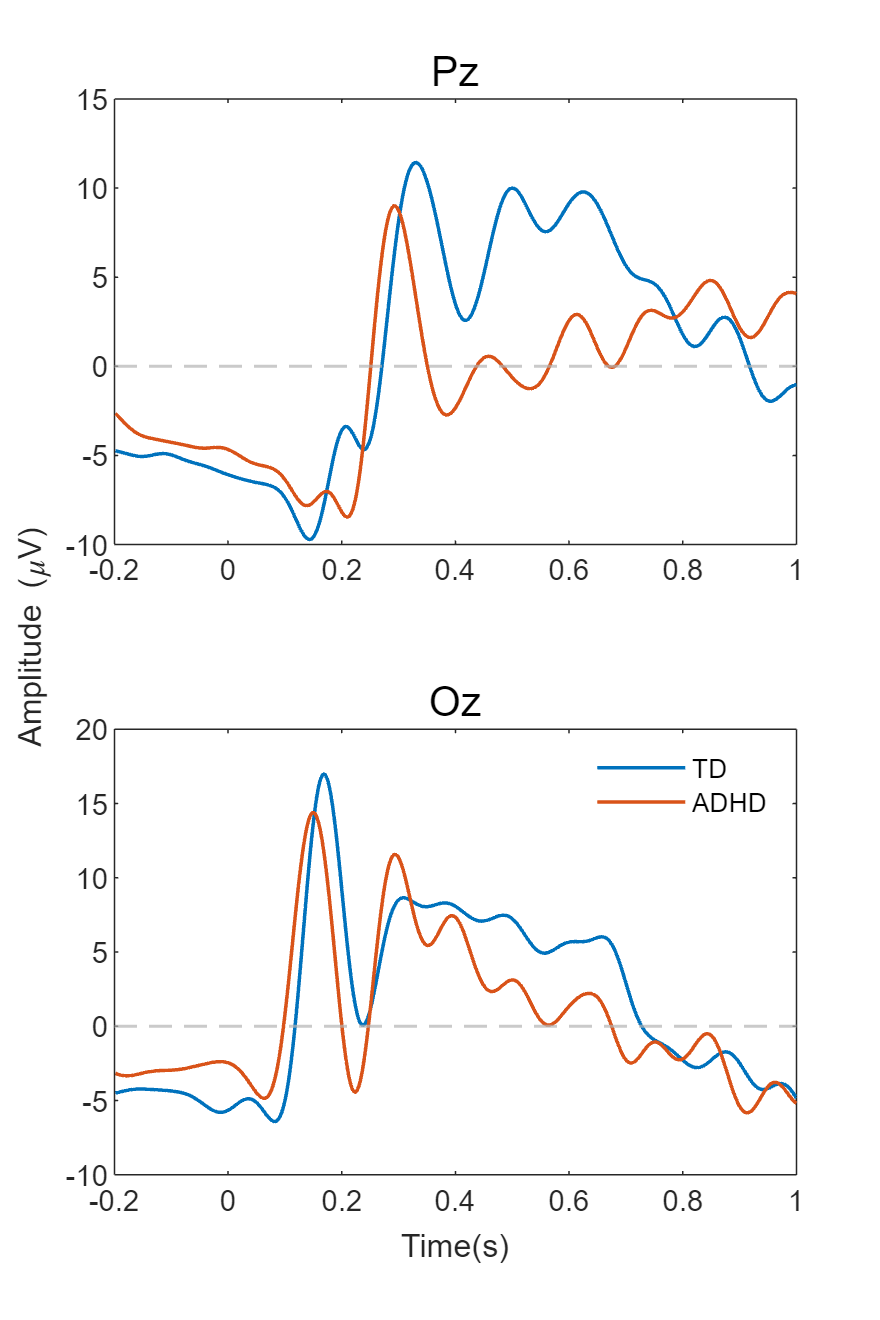

ch_idx = [26 30]; % Pz, Oz

figure('Position', [400 40 400 600]);
tiledlayout(2,1);
for ich = ch_idx
    nexttile();

    plt(1) = plot(time, mean(EEG_TD(ich, :, :), 3), 'LineWidth', 1.2);
    hold on;
    plt(2) = plot(time, mean(EEG_ADHD(ich, :, :), 3), 'LineWidth', 1.2);
    title(ChanName{ich}, 'FontSize', 14);
    
    yline(0, '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);

end

% legend options
legend(plt, {'TD', 'ADHD'}, 'Location', 'best', 'box', 'off')

% figure options
ax = axes('Visible', 'off');
ax.XLabel.Visible = 'on';
ax.YLabel.Visible = 'on';
xlabel('Time(s)');
ylabel('Amplitude (\muV)');

**Reshape EEG data to be suitable for K-means**

: Flatten each trial to create a 2D feature matrix [samples x features]

X_total = reshape(EEG_Total(:, timeidx, :), n_ch * size(EEG_Total(:, timeidx, :), 2), [])';
size(X_total)

ans =          400        7750


**Label**

lb = [zeros(size(EEG_TD, 3), 1); ones(size(EEG_ADHD, 3), 1)];
size(lb)

ans =    400     1


**Apply PCA**

% PC: A matrix where each column represents a principal component(PC)
% score: The transformed data in the new principal component space
% explained: A vector that shows the percentage of the total variance explained by each principal component

[PC,score,~,~,explained] = pca(X_total);

size(PC)

ans =         7750         399


size(score)

ans =    400   399


% Only the PCs that explained 90% of the variance in the data were retained.
sum_explaiend = cumsum(explained);
idx = find( sum_explaiend <= 90 );

**Apply K-means using PCA**

[idx_total, centers]  = kmeans(score(:,idx), 2, 'Distance', 'sqeuclidean'); % Cluster indices

% Accuracy calculation for all data
accuracy_all = max(mean((lb == 0 & idx_total == 1) | (lb == 1 & idx_total == 2)), ...
                   mean((lb == 0 & idx_total == 2) | (lb == 1 & idx_total == 1)));

fprintf('K-means Clustering Accuracy (All Data): %.2f%%\n', accuracy_all * 100);

K-means Clustering Accuracy (All Data): 66.25%


**Visualization**

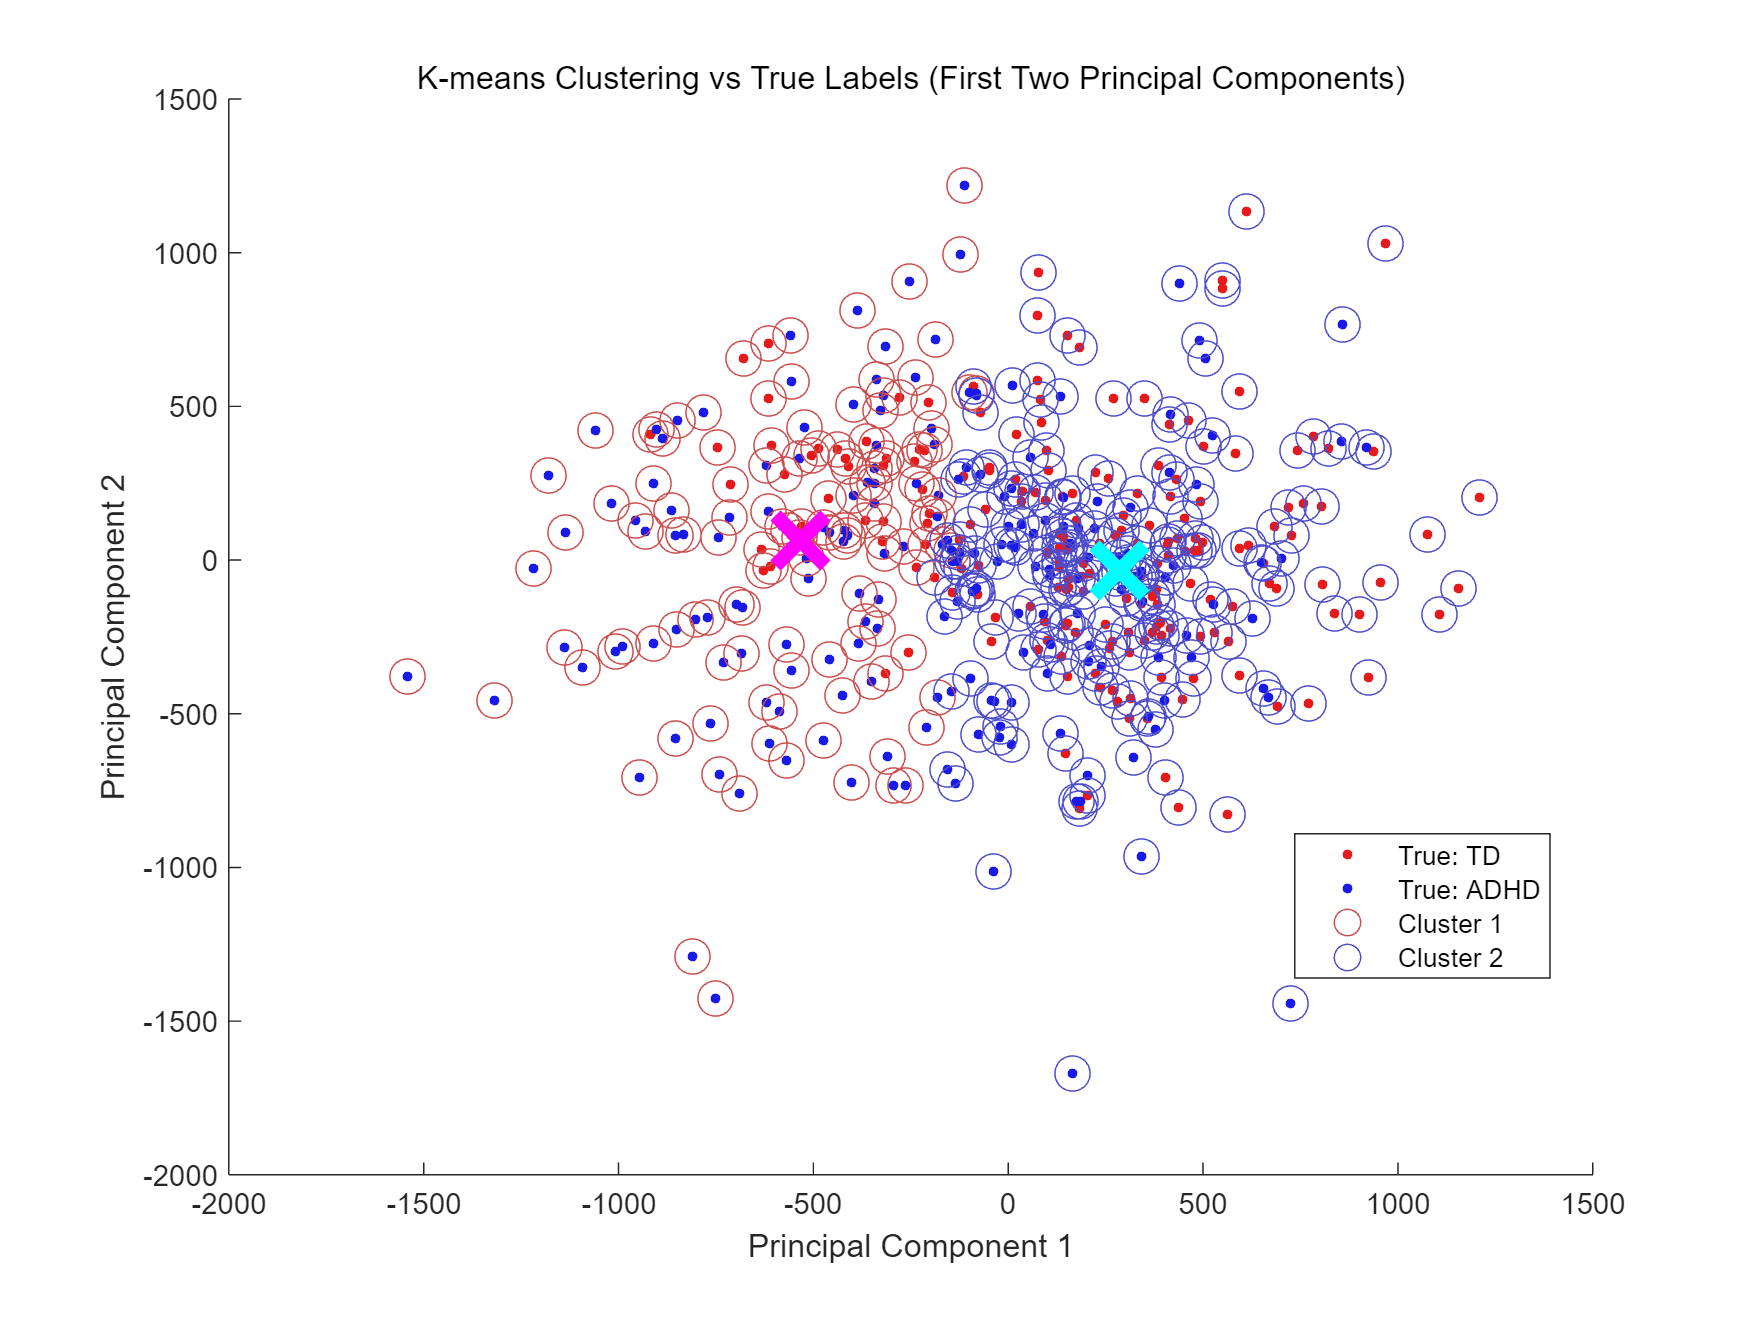

% Use the first two principal components for visualization
score_2D = score(:, 1:2);

% Define red and blue tones for clear distinction
true_colors = [0.9, 0.1, 0.1; 0.1, 0.1, 0.9]; % TD: Red, ADHD: Blue
cluster_colors = [0.8, 0.3, 0.3; 0.3, 0.3, 0.8]; % Cluster 1: Light Red, Cluster 2: Light Blue

% Create a figure for scatter plots
figure('Position', [100, 100, 800, 600]);
hold on;

% True labels (dots)
gscatter(score_2D(:,1), score_2D(:,2), lb, true_colors, '..', 10);

% Clustering results (hollow circles)
gscatter(score_2D(:,1), score_2D(:,2), idx_total, cluster_colors, 'oo', 12);

% Display centers
cgh = gscatter(centers(:,1), centers(:,2), unique(lb), 'mc', 'x', 24);
set(cgh, 'LineWidth',5);

% Add title, labels, and legend
legend({'True: TD', 'True: ADHD', 'Cluster 1', 'Cluster 2'}, 'Location', 'best');
title('K-means Clustering vs True Labels (First Two Principal Components)');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
hold off;